# Laboratorium 1

# Przypomnienie podstaw środowiska Matlab oraz podstaw przetwarzania sygnałów.

## Zadanie rozgrzewkowe 1

Rozwiąż układ równań

x+2y+3z=1

4x+5,5y+6z=1

7x+8y+9,5z=1

syms x y z;

eqn1 = x + 2*y + 3*z == 1;
eqn2 = 4*x + 5.5*y + 6*z == 1;
eqn3 = 7*x + 8*y + 9.5*z == 1;

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z]);
X = linsolve(A, B);
X

$$X = \left(\begin{array}{c} -\frac{19}{29}\\ \frac{6}{29}\\ \frac{12}{29} \end{array}\right)$$

## Zadanie rozgrzewkowe 2

Sporządź wykres okręgu (równania parametryczne) dla t=[0;1)

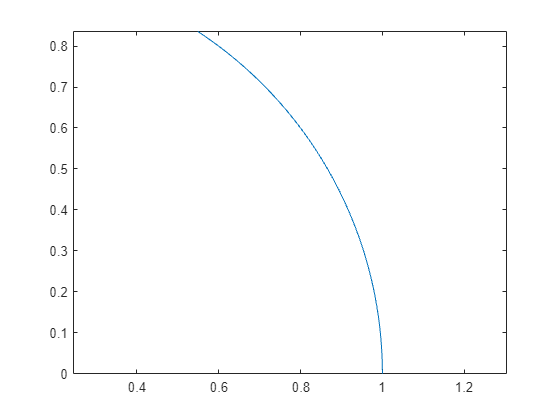

t = 0:0.01:1-0.01;
x = cos(t);
y = sin(t);


plot(x,y)
axis equal

## Zadanie rozgrzewkowe 3

Wygeneruj i przedstaw graficznie 3 okresy sygnałów. Amplituda A=+/- 1V, dla każdego wyznaczyć składową stałą i moc.

- Przebieg harmoniczny o częstotliwości f=1kHz

- Przebieg prostokątny o częstotliwości f=1kHz, wypełnieniu k=1/2 

- Przebieg piłokształtny o częstotliwości f=1kHz

- Przebieg trójkątny o częstotliwości f=1kHz

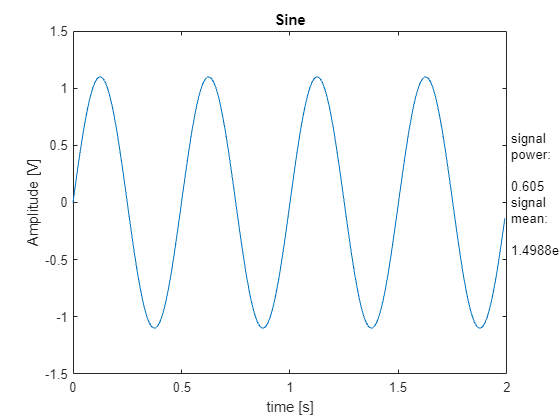

A = 1.1;
f =2;
k = 0.8;

w = 2*pi*f;
tmin = 0;
tmax = 2;
dt = 0.01;
t = tmin:dt:tmax-dt; %s

ad1 = A*sin(w*t);
power_ad1 = rms(ad1)^2;
mean_ad1 = mean(ad1);

plot(t, ad1);
title('Sine')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad1), 'signal mean: ', string(mean_ad1)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

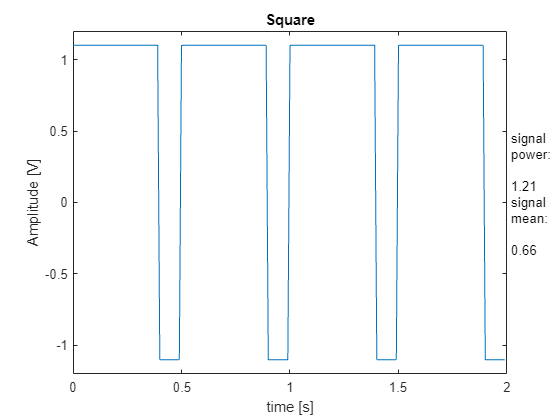

first_half = ones(1, round(1/(f*dt)*k)); second_half =  -1 * ones(1, round((1/(f*dt))*(1-k)));
ad2 = A * [first_half second_half];
for i = 0:(1/f)+1
    ad2 = cat(2,ad2,ad2);
end
power_ad2 = rms(ad2)^2;
mean_ad2 = mean(ad2);

plot(t, ad2)
ylim([-A-.1, A+0.1])
title('Square')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad2), 'signal mean: ', string(mean_ad2)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

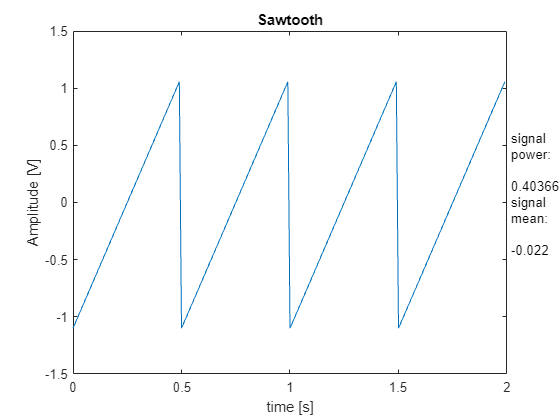

ad3 = A * sawtooth(w*t);
power_ad3 = rms(ad3)^2;
mean_ad3 = mean(ad3);

plot(t, ad3)
title('Sawtooth')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad3), 'signal mean: ', string(mean_ad3)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

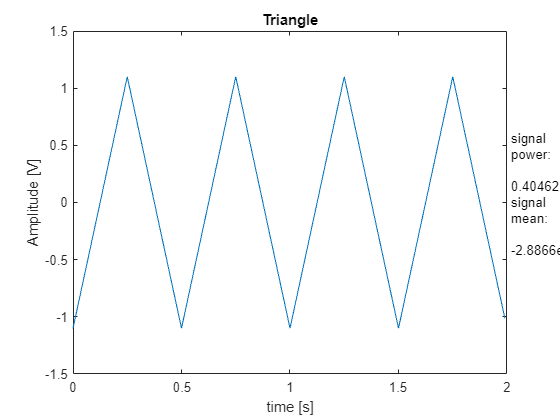


ad4 = A * sawtooth(w*t, .5);
power_ad4 = rms(ad4)^2;
mean_ad4 = mean(ad4);

plot(t, ad4)
title('Triangle')
ylabel('Amplitude [V]')
xlabel('time [s]')
txt = ['signal power: ', string(power_ad4), 'signal mean: ', string(mean_ad4)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

## ***Zad 1***

***Zbudować przebieg „prostokątny” o częstotliwości f=30Hz za pomocą funkcji sinusoidalnych***

- Trzech

- Pięciu

- Dziesięciu

- Stu

- Analiza przypadku (1): sygnał cyfrowy ma częstotliwość 1 MHz (2 Mbit/s), jest reprezentowany odpowiednio przez 1 i 3 oraz 1 i 3 i 5 harmoniczną, szerokość pasma, reprezentacja sygnału.

#### Opis problemu:

Każdy sygnał okresowy, spełniający warunki Dirichleta może być zbudowany za pomocą sumy sinusów różnych częstotliwości i amplitud. Sygnał prostokątny o częstotliwości f i amplitudzie A składa się z nieskończonej ilości nieparzystych harmonicznych do częstotliwości f, których amplitudy wynoszą A/n gdzie n to numer danej harmonicznej.

#### Podstawy matematyczne:

**Szereg Fouriera** – szereg pozwalający rozłożyć funkcję okresową, spełniającą warunki Dirichleta, na sumę funkcji trygonometrycznych. 

#### Symulacja:

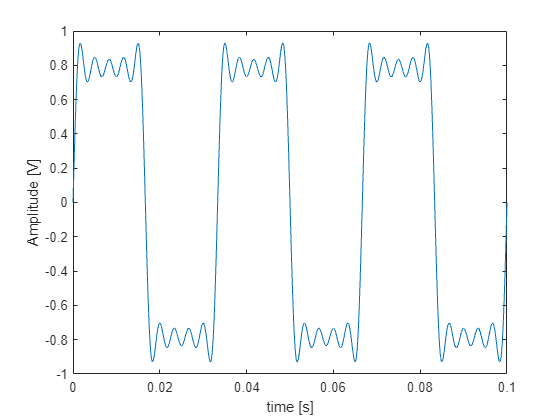

N_sines = 5;

t = 0:0.00001:3/30;
combined_sines = zeros(size(t));

for i = 1:2:N_sines*2
    combined_sines = combined_sines + (1/i) * sin(2*pi*30*i*t);
end



plot(t, combined_sines)
ylabel('Amplitude [V]')
xlabel('time [s]')

#### Obserwacje:

Wraz ze wzrostem ilości harmonicznych składających się na nasz sygnał, jego kształt jest coraz bardziej zbliżony do sygnału prostokątnego.

#### Wnioski:

Aby idealnie odwzorować przebieg prostokątny musieli byśmy złożyć go z nieskończonej ilości harmonicznych.

## **Zad 2**

Dla sygnału analogowego: $f{\left(t\right)}=5+2cos{\left(2\pi t-\frac{\pi }{2}\right)}+3\mathrm{c}\mathrm{o}\mathrm{s}\left(4\pi t\right)$

- Dobierz  częstotliwość próbkowania fs sygnału f(t). Zaproponuj czas obserwacji - konsekwencje. Wyznacz DFT sygnału (wskazy). 

- Zmieniając liczbę bitów przetwornika AC (np. bit = 1, 3, 4, 8, 10), zbadać: jak zmienia się obraz próbkowanego sygnału, poziom (rząd wielkości) błędów kwantyzacji, porównać maksymalny błąd kwantyzacji z połową przedziału kwantowania, jakie zniekształcenia się pojawiają (wyższe harmoniczne sygnału), dla bit=1, 2, 4, 8 wyznacz współczynnik zawartości harmonicznych. Określ odstęp i szum kwantyzacji.

#### Opis problemu:

Jak należy dobierać parametry przetwornika analogowo cyfrowego takie jak czas obserwacji, częstotliwość próbkowania oraz ilość bitów adc aby otrzymać poprawne cyfrowe odwzorowanie próbkowanego sygnału? Jaki wpływ zmiany tych parametrów mają na widmo dft sygnału oraz próbkowany sygnał?

#### Podstawy matematyczne:

Twierdzenie o próbkowaniu - Jeśli sygnał ciągły nie ma składowych widma o częstotliwości równej lub większej niż B, może on zostać jednoznacznie odtworzony z ciągu jego próbek tworzących sygnał dyskretny, o ile próbki te zostały pobrane z częstotliwością co najmniej 2B.

Warunki transformaty fouriera - funkcja musi spełniać warunki dirichleta tzn dziedzinę f(x) można rozłożyć na skończoną sumę przedziałów, w których f(x) jest monotoniczna i ciągła oraz w każdym punkcie nieciągłości x0 , granice jednostronne limx→x − 0 f(x) i limx→x + 0 f(x) są skończone. Funkcja musi być całkowalna i ciągła w całym przedziale.

#### Symulacje:

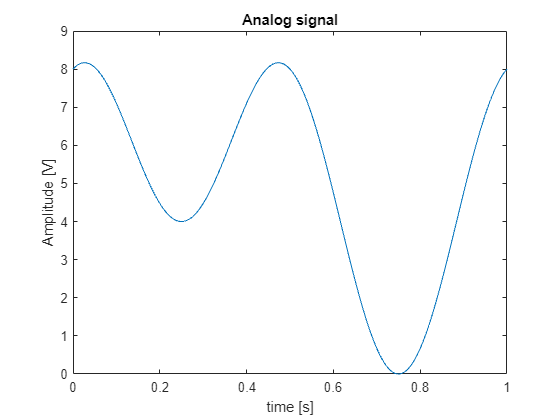

observation_time = 1; %observation time [seconds] %N
sampling_frequency = 42; % sampling frequency [Hz]
ADC_bits = 3; % number of adc bits


fs = sampling_frequency;
bits = ADC_bits;

t = 0:0.001:observation_time;
signal = 5 + 2*cos(2*pi*t-pi/2) + 3*cos(4*pi*t);

Q = (max(signal)/2^bits); % adc qwant
Ts = 1/fs; %sampling period
N = observation_time/Ts; %number of samples

n = 0:N-1;

sampled_signal = floor((5 + 2*cos(2*pi*(n*Ts)-pi/2) + 3*cos(4*pi*n*Ts)) / Q) * Q;

interpolated_signal = imresize(sampled_signal, [1 length(t)], 'nearest');
q_error = max(signal - interpolated_signal);

signal_fft = fft(sampled_signal);
frequency_vector = (fs/length(n))*(-length(n)/2:(length(n)/2)-1);


plot(t, signal)
title('Analog signal')
ylabel('Amplitude [V]')
xlabel('time [s]')

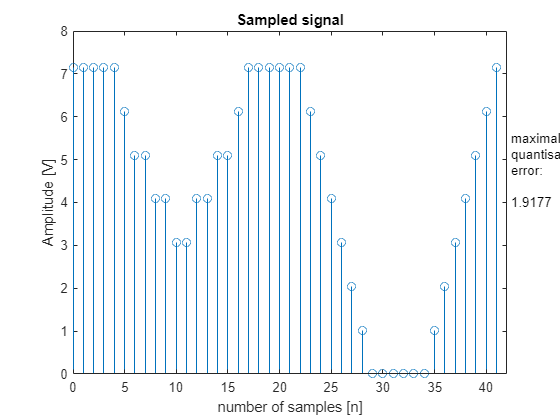



stem(n, sampled_signal)
xlim([0, N])
title('Sampled signal')
ylabel('Amplitude [V]')
xlabel('number of samples [n]')
txt = ['maximal quantisation error: ', string(q_error)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

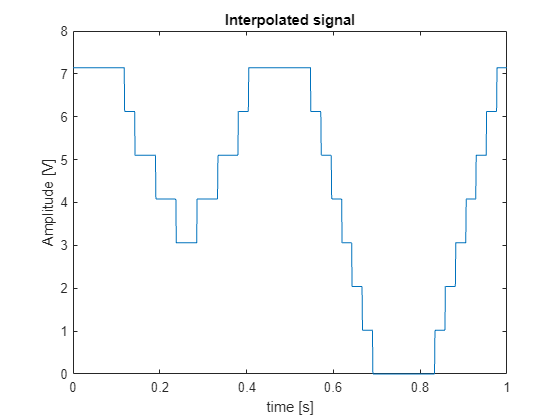



plot(t, interpolated_signal)
title('Interpolated signal')
ylabel('Amplitude [V]')
xlabel('time [s]')

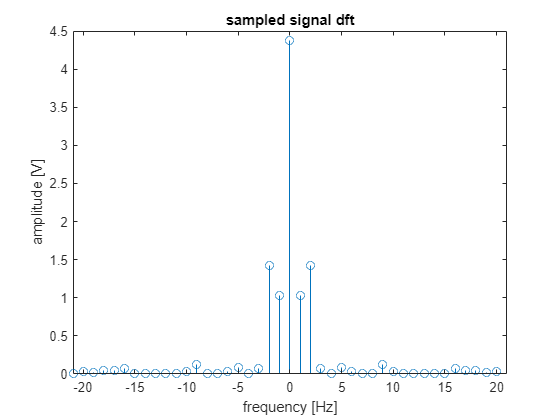



stem(frequency_vector, abs(fftshift(signal_fft))/length(n))
xlim([-fs/2, fs/2])
title('sampled signal dft')
xlabel('frequency [Hz]')
ylabel('amplitude [V]')

#### Obserwacje:

Przy poprawnie dobranych częstotliwości próbkowania i czasie obserwacji na widmie dft obserwujemy składową stałą sygnału o amplitudzie równej 5 oraz dwa prążki odpowiadające składowym o częstotliwościach 1Hz i 2Hz co zgadza się z parametrami próbkowanego sygnału.

Sygnał może być odwzorowany dopiero gdy częstotliwość próbkowania wynosi 4Hz, tzn 2xczęstotliwość najwyższej harmonicznej sygnału. Dalsze zwiększanie częstotliwości próbkowania pozwala na coraz dokładniejsze odwzorowanie.

Taki sam efekt ma zwiększanie ilości bitów przetwornika. Im mniej bitów przetwornika tym mniej poszczególnych poziomów sygnały jesteśmy w stanie zarejestrować co powoduje zwiększenie błędu kwantyzacji.

Stosując czas obserwacji inny niż wielokrotność 1Hz w widmie częstotliwościowym pojawiają się harmoniczne wynikające z nieciągłości powstałych na granicach sygnału.

#### Wnioski:

Aby dokładnie odwzorować sygnał należy stosować częstotliwość próbkowania 10x większą od najwyższej częstotliwości składowej sygnału.

Czas obserwacji musi wynosić wielokrotność okresu składowej o najniższej częstotliwości, w przeciwnym wypadku na granicach sygnału powstaną nieciągłości które pojawią się w widmie częstotliwościowym.

## **Zad 3**

#### Dla sygnału sinusoidalnego f=1kHz, porównać dwa przypadki: (1) fs= 8000 Hz, bit=8, pozostałe parametry domyślne, (2) fs= 8600 Hz, bit=8, pozostałe parametry domyślne. Opisać zaobserwowane zjawisko (widmo).

#### Analogicznie dla sygnału mowy o paśmie 300Hz - 3400Hz; (1) fs= 8000 Hz, bit=8, (2) fs= 8600 Hz, bit=8

#### Opis problemu:

Jak należy dobierać częstotliwość próbkowania aby prawidłowo odwzorować póbkowany sygnał i wpływ na widmo tego sygnału.

#### Podstawy matematyczne:

Twierdzenie o próbkowaniu. 

time = 2100/1000000 %us

time = 0.0021

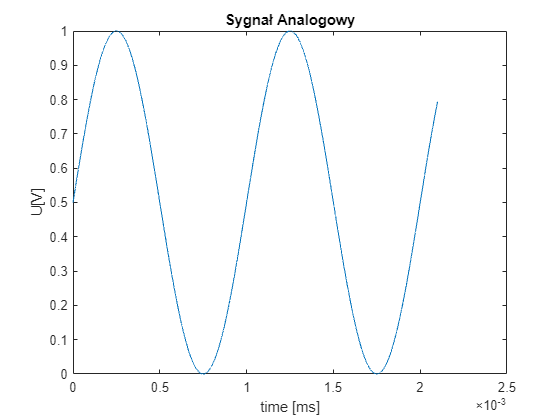




f = 1000; % Częstotliwość sygnału sinusoidalnego (Hz)
fs = 8000; % Częstotliwość próbkowania (Hz)
bit_resolution = 8; %rozdzielczość

T = 1/fs; %sampling period
n = 0:time/T; %number of samples in observation time


% Parametry sygnału analogowego

tmin = 0;
tmax = 1;
dt = 0.0000001;
t = 0:1/fs:time; 
tsin = tmin:dt:time-dt; 
A = 0.5; % Amplituda

% Sygnał sinusoidalny
analog_signal = A + (A * sin(2 * pi * f * tsin));

% Symulacja próbkowania
t_adc = 0:1/fs:time-1/fs; % Wektor czasu dla próbkowania
sampled_signal = interp1(tsin, analog_signal, t_adc, 'linear');

% Symulacja kwantyzacji 
bit_val = (2 * A) / ((2 ^ bit_resolution)); %wartość pojedyńczego kwantu
quantized_signal = floor(sampled_signal/bit_val);

quantized_signal = quantized_signal * bit_val;

% Wykres sygnału analogowego
plot(tsin, analog_signal);
xlabel("time [ms]")
ylabel("U[V]")
title('Sygnał Analogowy');

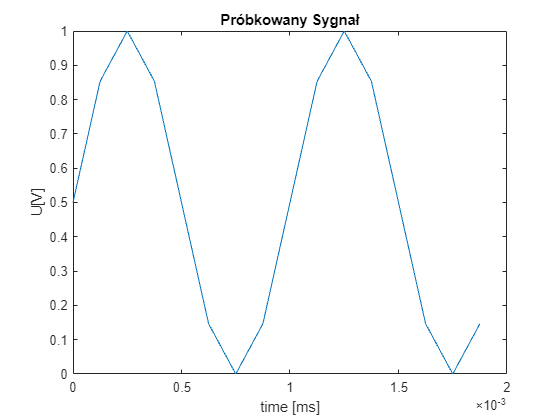


% Wykres próbkowanego sygnału
plot(t_adc, sampled_signal);
xlabel("time [ms]")
ylabel("U[V]")
title('Próbkowany Sygnał');

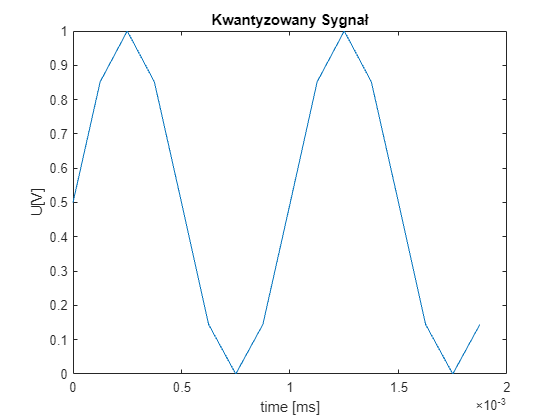


% Wykres kwantyzowanego sygnału
plot(t_adc, quantized_signal);
xlabel("time [ms]")
ylabel("U[V]")
title('Kwantyzowany Sygnał');

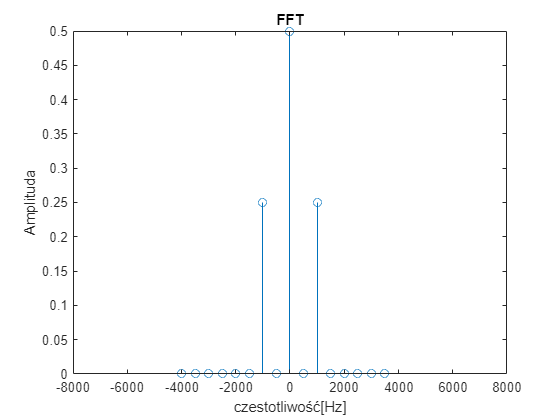

signal_fft = fft(quantized_signal);
frequency_vector = (fs/length(t_adc))*(-length(t_adc)/2:(length(t_adc)/2)-1);

stem(frequency_vector, abs(fftshift(signal_fft))/length(t_adc))
xlim([-fs, fs])

title('FFT');
xlabel('czestotliwość[Hz]');
ylabel('Amplituda')

#### Obserwacje:

Sygnał sinusoidalny próbkowany wielokrotnością jego czestotliwości zawiera dwie składowe, gdy częstotliwość próbkowania nie jest wielokrotnością czestotliwości próbkowanej w widmie sygnału pojawiają się dodatkowe prażki częstotliwości, jest to nieporządane zjawisko.

#### Wnioski:

Sygnał nalezy próbkować częstotliwością, która jest jego wielokrotnością. 

## zad 4a)

***Widmo DFT sygnałów rzeczywistych***

Proszę nie używać wbudowanej funkcji *conv i dft*.

- Wygeneruj N = 20 próbek sygnałów sinusoidalnych mających odpowiednio W = {1,3,5,9} okresów. Oblicz widmo DFT, wykreśl część rzeczywistą i urojoną widma oraz widmo amplitudowe i fazowe. Jaka powinna być część rzeczywista widma DFT sygnału sinusoidalnego? Oceń otrzymane wyniki. Jak zinterpretować otrzymaną fazę widma? Stwórz funkcje likwidującą błędy odcięcia wartości zerowych części rzeczywistej i urojonej. Powtórz ww. czynności dla sygnałów kosinusoidalnych dla tych samych wartości N i W. (indeksy osi x przyjmij 0….N-1, wartość fazy znormalizuj względem pi) 

#### Opis problemu:

Zadanie polega na wygenerowaniu 20 próbek przebiegów sinusoidalnych oraz kosinusoidalnych o różnych okresach oraz obliczeniu dyskretnej transformaty Fouriera dla każdego z nich i zaprezentowaniu części rzeczywistej, urojonej, widma amplitudowego i fazowego.

#### Podstawy matematyczne:

Dyskretna transformata Fouriera  została zaimplementowana w funkcji my_fft() na końcu dokumentu. Części rzeczywista i urojona spektrum częstotliwościowego zostały wyodrębnione za pomocą wbudowanych funkcji matlaba real() oraz imag(). Spektrum amplitudowe zostało wyodrębnione za pomocą wbudowanej funkcji abs() liczącej wartość bezwzględną, a spektrum fazowe za pomocą funkcji angle() liczącą przesunięcie fazowe.

Błędy odcięcia (truncation errors) wartości zerowych wynikające z skończonych zakresów zmiennych zostały zlikwidowane za pomocą funcji remove_errors() zaimplementowanej na końcu dokumentu.

#### Symulacje:

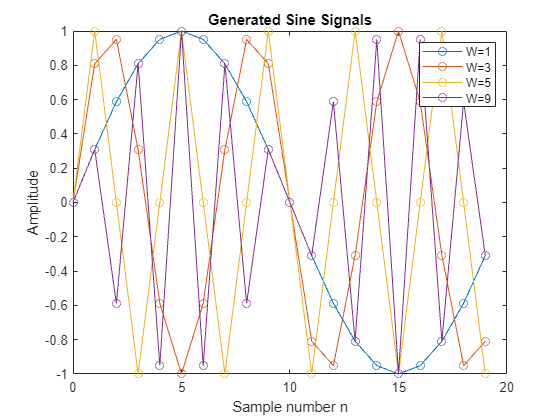

N = 20;
n = 0:N-1;

sin_W1 = sin(2*pi*n/N);
sin_W3 = sin(2*pi*3*n/N);
sin_W5 = sin(2*pi*5*n/N);
sin_W9 = sin(2*pi*9*n/N);


plot(n, sin_W1, '-o', n, sin_W3, '-o', n, sin_W5, '-o', n, sin_W9, '-o')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('Amplitude')
xlabel('Sample number n')
title('Generated Sine Signals')

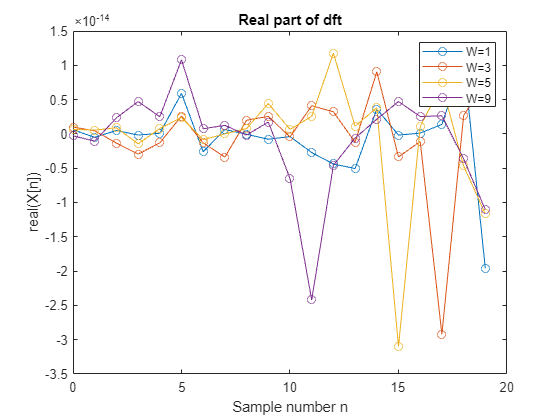


sin_W1_dft = my_dft(sin_W1);
sin_W3_dft = my_dft(sin_W3);
sin_W5_dft = my_dft(sin_W5);
sin_W9_dft = my_dft(sin_W9);

plot(0:N-1, real(sin_W1_dft), '-o', 0:N-1, real(sin_W3_dft), '-o', 0:N-1, real(sin_W5_dft), '-o', 0:N-1, real(sin_W9_dft), '-o')
title('Real part of dft')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('real(X[n])')
xlabel('Sample number n')

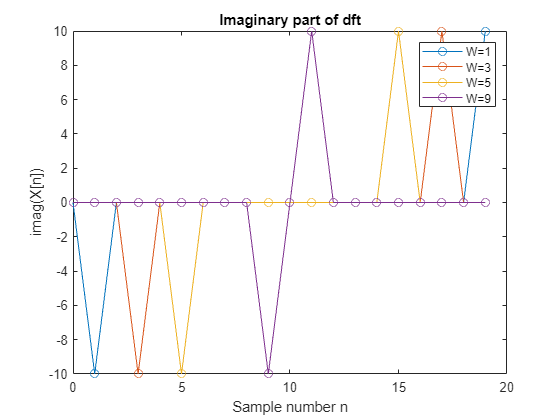

plot(0:N-1, imag(sin_W1_dft), '-o', 0:N-1, imag(sin_W3_dft), '-o', 0:N-1, imag(sin_W5_dft), '-o', 0:N-1, imag(sin_W9_dft), '-o')
title('Imaginary part of dft')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('imag(X[n])')
xlabel('Sample number n')

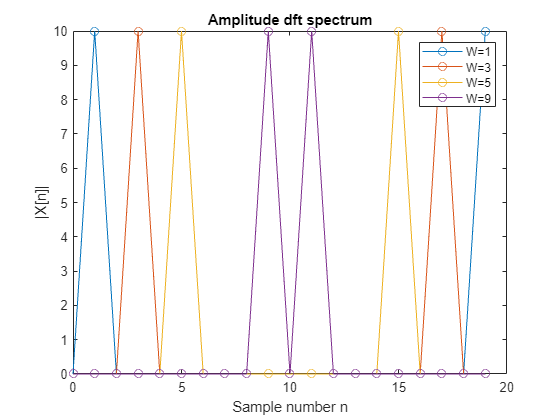

plot(0:N-1, abs(sin_W1_dft), '-o', 0:N-1, abs(sin_W3_dft), '-o', 0:N-1, abs(sin_W5_dft), '-o', 0:N-1, abs(sin_W9_dft), '-o')
title('Amplitude dft spectrum')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('|X[n]|')
xlabel('Sample number n')

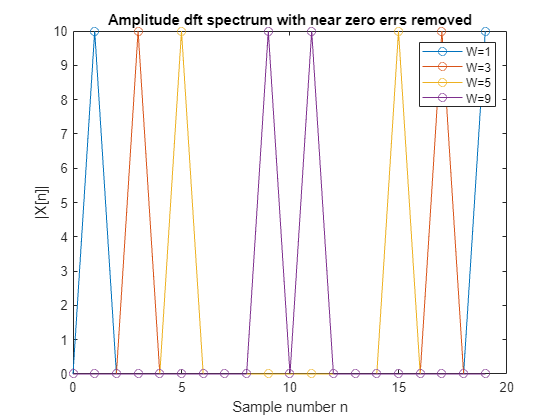

plot(0:N-1, abs(remove_errors(sin_W1_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(sin_W3_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(sin_W5_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(sin_W9_dft, 1e-6)), '-o')
title('Amplitude dft spectrum with near zero errs removed')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('|X[n]|')
xlabel('Sample number n')

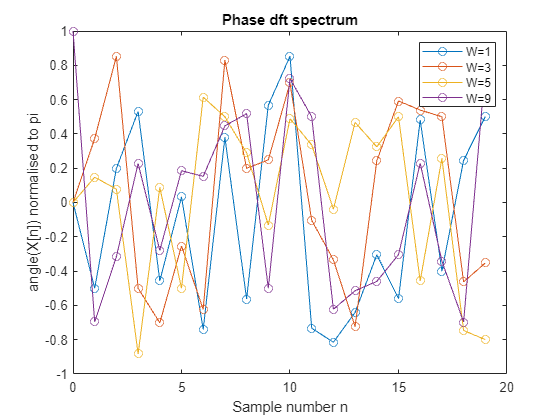


plot(0:N-1, angle(sin_W1_dft)/pi, '-o', 0:N-1, angle(sin_W3_dft)/pi, '-o', 0:N-1, angle(sin_W5_dft)/pi, '-o', 0:N-1, angle(sin_W9_dft)/pi, '-o')
title('Phase dft spectrum')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('angle(X[n]) normalised to pi')
xlabel('Sample number n')

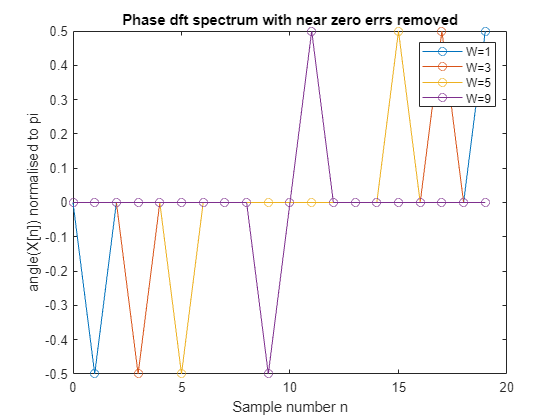

plot(0:N-1, angle(remove_errors(sin_W1_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(sin_W3_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(sin_W5_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(sin_W9_dft, 1e-6))/pi, '-o')
title('Phase dft spectrum with near zero errs removed')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('angle(X[n]) normalised to pi')
xlabel('Sample number n')

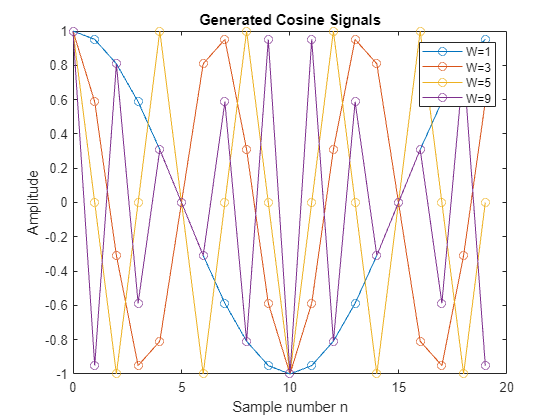


cos_W1 = cos(2*pi*n/N);
cos_W3 = cos(2*pi*3*n/N);
cos_W5 = cos(2*pi*5*n/N);
cos_W9 = cos(2*pi*9*n/N);


plot(n, cos_W1, '-o', n, cos_W3, '-o', n, cos_W5, '-o', n, cos_W9, '-o')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('Amplitude')
xlabel('Sample number n')
title('Generated Cosine Signals')

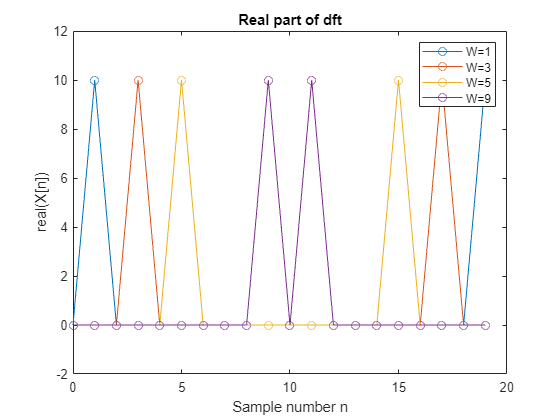

cos_W1_dft = my_dft(cos_W1);
cos_W3_dft = my_dft(cos_W3);
cos_W5_dft = my_dft(cos_W5);
cos_W9_dft = my_dft(cos_W9);
plot(0:N-1, real(cos_W1_dft), '-o', 0:N-1, real(cos_W3_dft), '-o', 0:N-1, real(cos_W5_dft), '-o', 0:N-1, real(cos_W9_dft), '-o')
title('Real part of dft')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('real(X[n])')
xlabel('Sample number n')

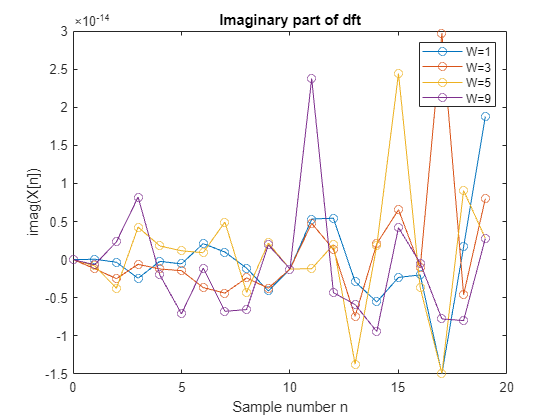


plot(0:N-1, imag(cos_W1_dft), '-o', 0:N-1, imag(cos_W3_dft), '-o', 0:N-1, imag(cos_W5_dft), '-o', 0:N-1, imag(cos_W9_dft), '-o')
title('Imaginary part of dft')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('imag(X[n])')
xlabel('Sample number n')

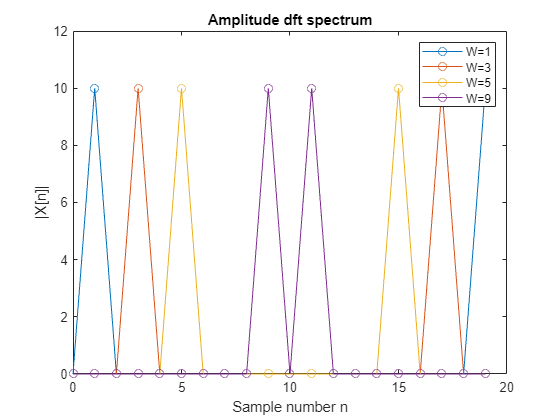

plot(0:N-1, abs(cos_W1_dft), '-o', 0:N-1, abs(cos_W3_dft), '-o', 0:N-1, abs(cos_W5_dft), '-o', 0:N-1, abs(cos_W9_dft), '-o')
title('Amplitude dft spectrum')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('|X[n]|')
xlabel('Sample number n')

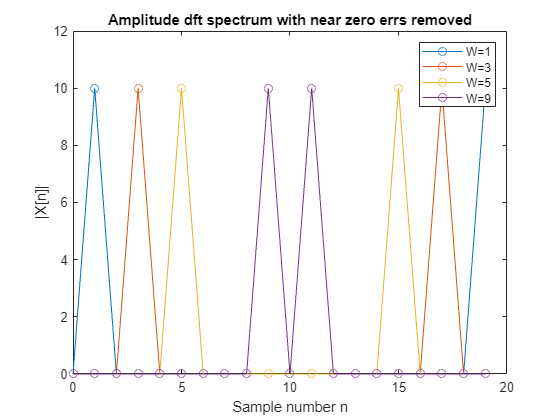


plot(0:N-1, abs(remove_errors(cos_W1_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(cos_W3_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(cos_W5_dft, 1e-6)), '-o', 0:N-1, abs(remove_errors(cos_W9_dft, 1e-6)), '-o')
title('Amplitude dft spectrum with near zero errs removed')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('|X[n]|')
xlabel('Sample number n')

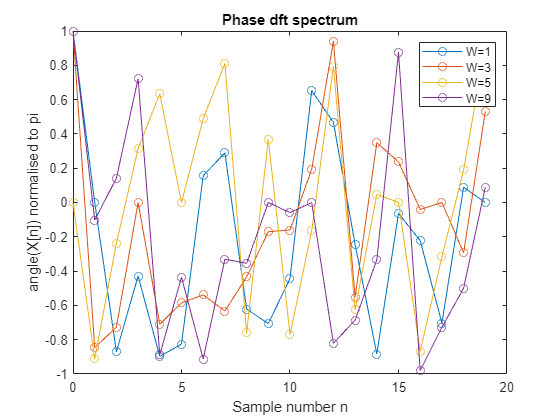


plot(0:N-1, angle(cos_W1_dft)/pi, '-o', 0:N-1, angle(cos_W3_dft)/pi, '-o', 0:N-1, angle(cos_W5_dft)/pi, '-o', 0:N-1, angle(cos_W9_dft)/pi, '-o')
title('Phase dft spectrum')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('angle(X[n]) normalised to pi')
xlabel('Sample number n')

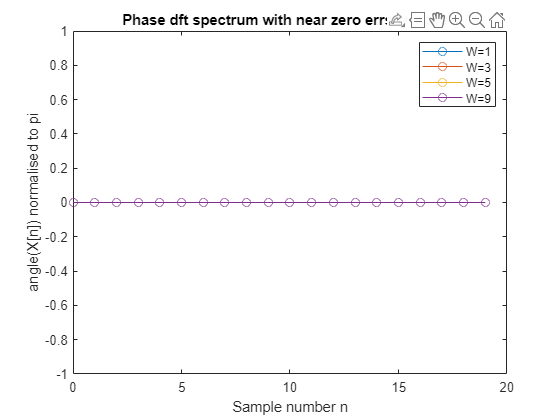


plot(0:N-1, angle(remove_errors(cos_W1_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(cos_W3_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(cos_W5_dft, 1e-6))/pi, '-o', 0:N-1, angle(remove_errors(cos_W9_dft, 1e-6))/pi, '-o')
title('Phase dft spectrum with near zero errs removed')
legend('W=1', 'W=3', 'W=5', 'W=9')
ylabel('angle(X[n]) normalised to pi')
xlabel('Sample number n')

#### Obserwacje:

Obserwując generowane sygnały zauważamy, że im więcej okresów danego sygnału chcemy zmieścić w jedynie 20 próbkach, tym mniej dokładnie odwzorowane są te sygnały.

Obserwując składowe rzeczywiste dft widzimy wartości bliskie 0 dla sygnałów sinusoidalnych i odwzorowanie sygnału wejściowego dla sygnałów kosinusoidalnych. Dla składowych urojonych zależność jest odwrotna.

Na widmach amplitudowych obserwujemy odbite symetrycznie pojedyncze prążki odpowiadające ilości okresów sygnału.

Widma fazowe po usunięciu błędów odcięcia blisko zera są takie same jak widma składowych urojonych, ponieważ obydwa mówią nam o przesunięciu fazowym sygnału.

#### Wnioski:

Systemy komputerowe cechują się niedokładnościami wynikającymi z skończonej dokładności zmiennych. Tutaj objawiają się one jako błedy w wartościach bliskich zero. Usuwamy je stosowną funkcją.

Im mniej dokładnie sporóbkowany zostanie nasz sygnał tym mniej idealnie wyglądać będą jego transformacje.

Składowa stała spektrum częstotliwościowego mówi nam o zawartości składowych cosinusowych w danym sygnale natomiast składowa urojona mówi nam o zawartości składowych sinusowych lub inaczej o przesunięciu fazowym.

## Zad4b)

- Wygeneruj N = 20 próbek sygnału  o częstotliwościach: f ={0.05fs, 0.08fs, 0.15fs, 0.24fs, 0.25fs, 0.43fs, 0.5fs, 0.57fs, 0.76fs, 1.08fs},  gdzie fs oznacza częstotliwość próbkowania. Opis osi częstotliwości widma znormalizuj względem częstotliwości próbkowania. Jaki związek zachodzi pomiędzy nr prążka widma, a rzeczywistą częstotliwością sygnału, gdy próbkujemy sygnał z częstotliwością fs? Które nr prążków są niezerowe (liczba porządkowa)? Czy zaobserwowano zjawisko przecieku widma? W jakiej proporcji nastąpił podział w każdym z przypadków? Ile powinna wynosić minimalna liczba próbek, aby zjawisko przecieku nie występowało? Ile wynosi rozdzielczość częstotliwościowa widma? Czy zaobserwowano zjawisko aliasingu? Wytłumacz na czym polega aliasing korzystając z ww. sygnałów. Które sygnały po ponownym odtworzeniu byłyby nierozróżnialne i dlaczego?

#### Opis problemu:

Ćwiczenie ma na celu pokazanie zależności pomiędzy częstotliwością sygnału i częstotliwością próbkowania w domienach czasu i częstotliwości. Należy zaobserwować i wyjaśnić zjawiska przecieku widmowego oraz aliasingu.

#### Podstawy matematyczne:

Aliasing - Zjawisko występujące gdy w sygnale próbkowanym z częstotliwością fs znajdują się składowe o częstotliwościach większych niż fs/2. Sygnału takiego nie jesteśmy w stanie poprawnie odtworzyć, a w domenie częstotliwości prążki częstotliwości większych od fs/2 nałożą się na widmo mniejszych częstotliwości.

Przeciek widmowy - Zjawisko występujące dla sygnałów których częstotliwości nie są wielokrotnościami częstotliwości próbkowania. Dla takich sygnałów, z powodu ich nieciągłości, energia widma częstotliwościowego rozlewa się na sąsiednie prążki, pomimo że w sygnale nie występują harmoniczne o danych częstotliwościach.

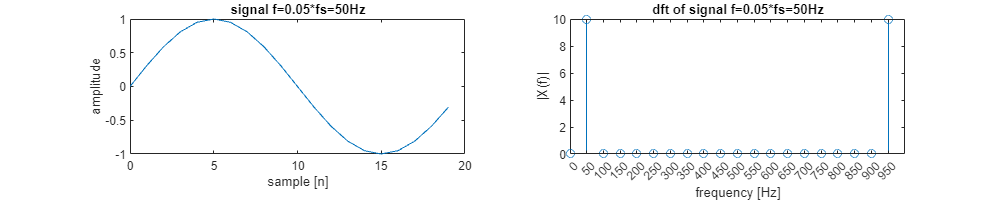

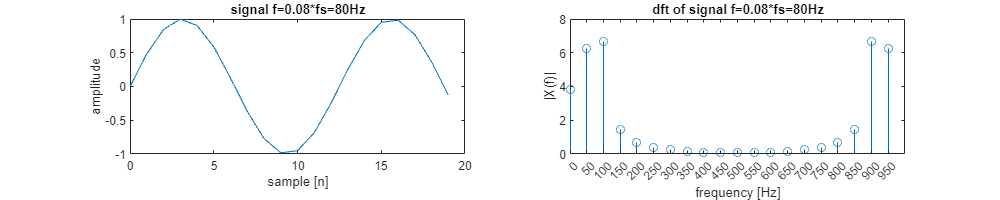

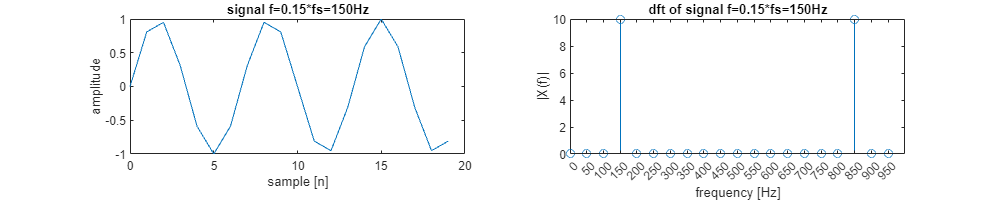

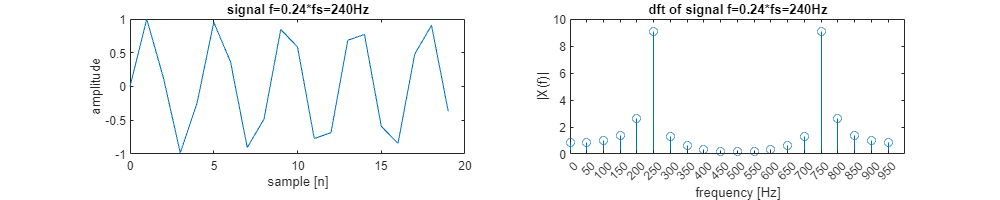

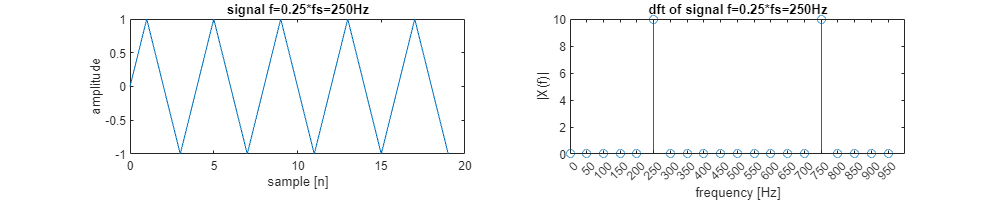

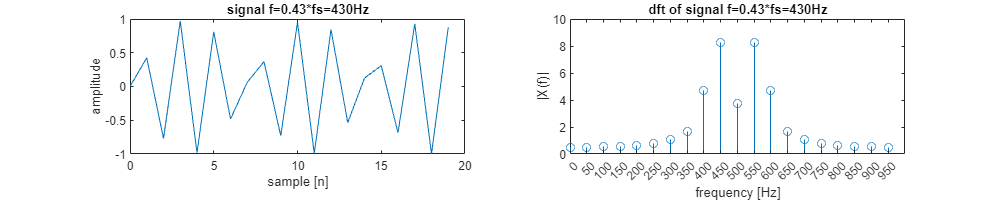

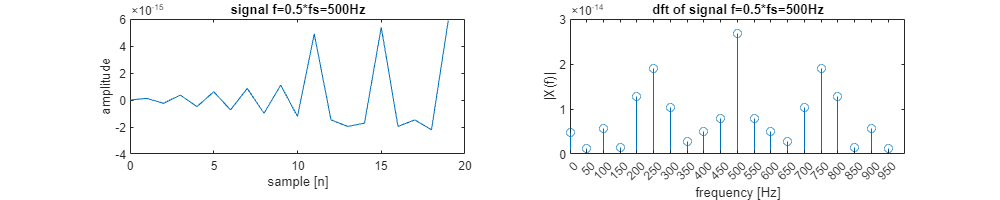

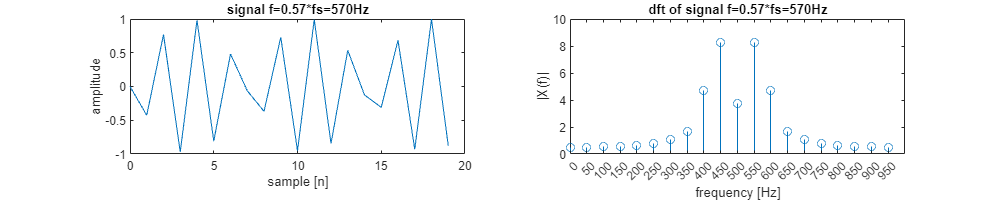

clc; clear; close all;
N = 20;
fs = 1000;

f = [.05 .08 .15 .24 .25 .43 .5 .57 .76 1.08];
n = 0:N-1;

for i = 1:length(f)
    sig = sin(2*pi*((f(i)*fs)/fs)*n);
    sig_dft = my_dft(sig);

    fig = figure;
    fig.Position = [0,0,1000,200];
    subplot(1, 2, 1)
    plot(n, sig)
    xlabel('sample [n]')
    ylabel('amplitude')
    title(['signal f=', num2str(f(i)), '*fs=', num2str(f(i)*fs), 'Hz'])

    subplot(1, 2, 2)
    stem((0:N-1)*fs/N, abs(sig_dft))
    title(['dft of signal f=', num2str(f(i)), '*fs=', num2str(f(i)*fs), 'Hz'])
    xlabel('frequency [Hz]')
    ylabel('|X(f)|')
    xticks((0:N-1)*fs/N)
end

#### Obserwacje:

Widmo częstotliwościowe jest odbiciem lustrzanym względem połowy częstotliwości fs.

Poszczególne prążki odpowiadają częstotliwością sygnału jedynie gdy nie zachodzi przeciek widma ani aliasing, tzn częstotliwość próbkowania jest wielkorotnością częstotliwości sygnału oraz jest od niego conajmniej 2x większa.

Zjawisko przecieku widma wystąpiło dla przebiegów f = 0.08fs oraz 0.24fs, w przypadkach f > 0.43fs wystąpiło zjawisko aliasingu.

#### Wnioski:

Sygnały o f > 0.43fs były by niemożliwe do odtworzenia. Nie byli byśmy w stanie odróżnić ich od przebiegów o niższych częstotliwościach.

Rozdzielczość częstotliwościowa analizy df wynosi df = fs/N, w naszym przypadku df = 1000Hz/20 = 50Hz

Aby nie występowało zjawisko przecieku widmowego, liczba próbek powinna być wielkrotnością okresu sygnału wejściowego.

## Zad4c)

- Wygeneruj N = 20 próbek sygnału prostokątnego x(n) = {1 dla 0 <= n <= L-1 ; 0 dla L <= n <= N-1}  dla L = {1, 2, 5, 10, 25, 50}. Oblicz widmo DFT, wykreśl część rzeczywistą, część urojoną widma oraz widmo amplitudowe i fazowe. Dla których indeksów prążki widma amplitudowego zerują się? Jaki jest stosunek amplitud kolejnych prążków? Co można powiedzieć  o symetrii części rzeczywistej i urojonej, amplitudy i fazy widma?

#### Opis problemu:

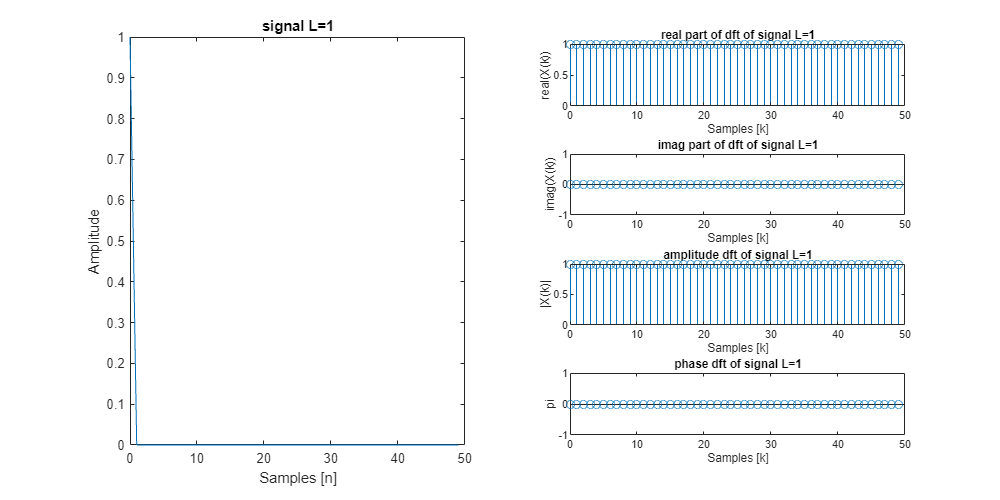

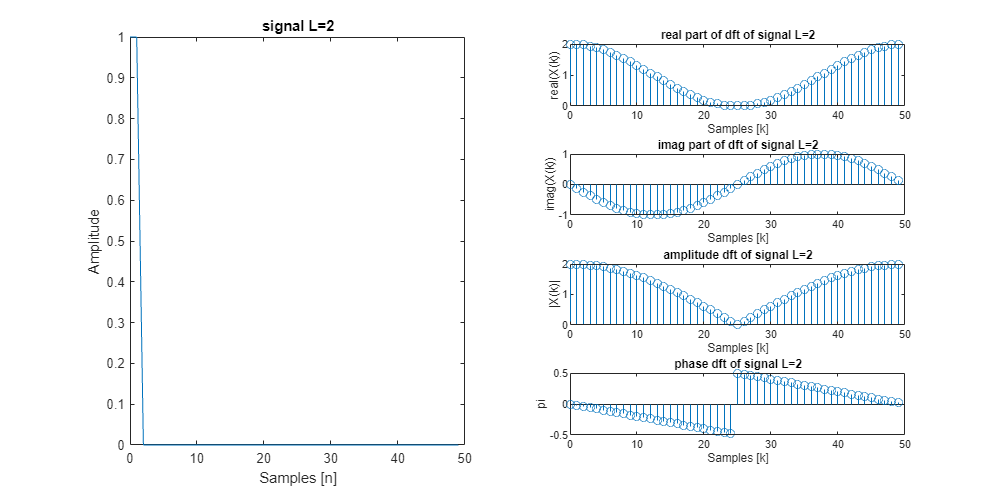

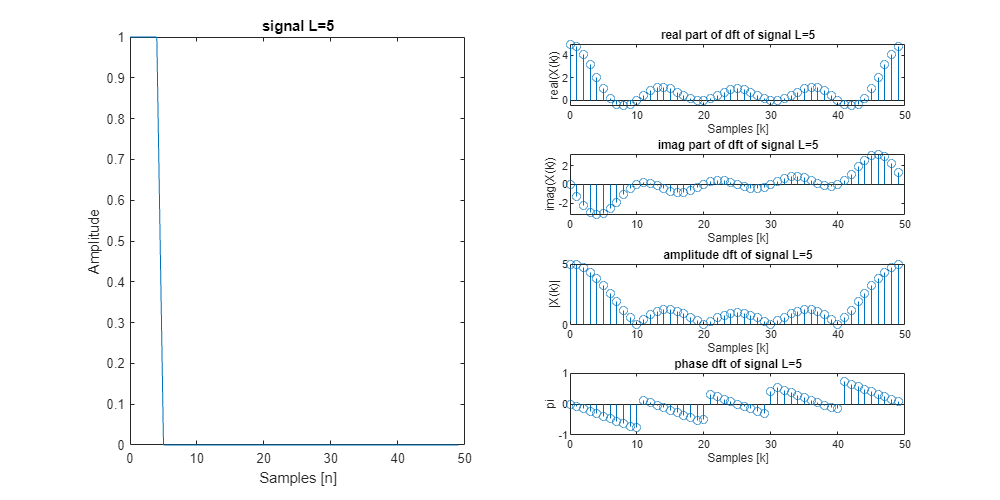

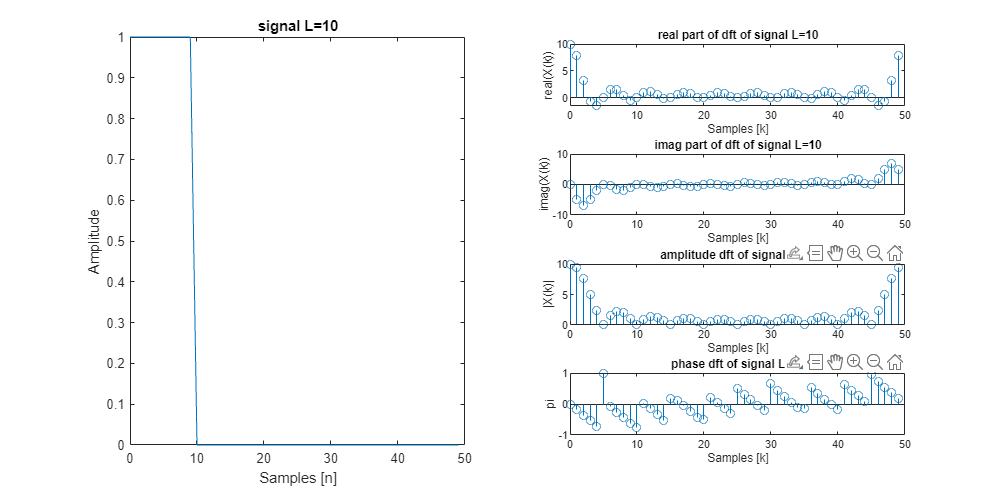

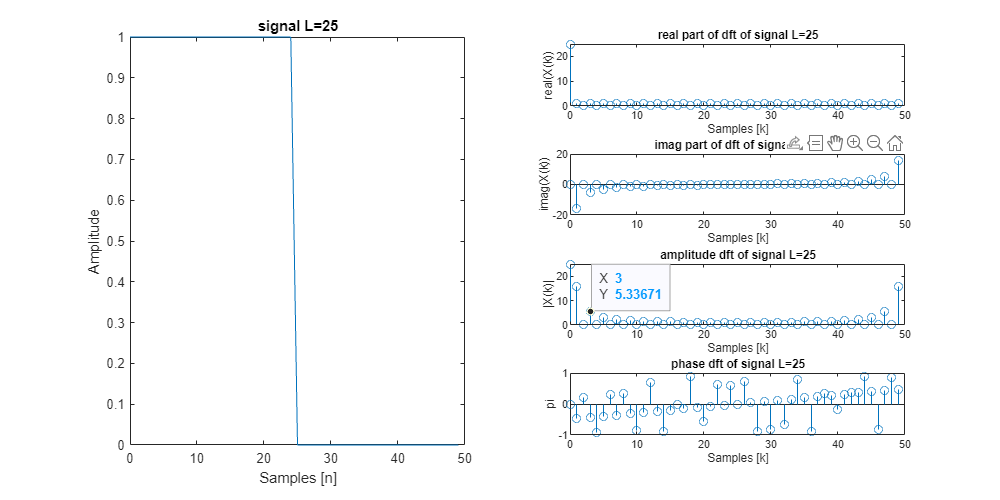

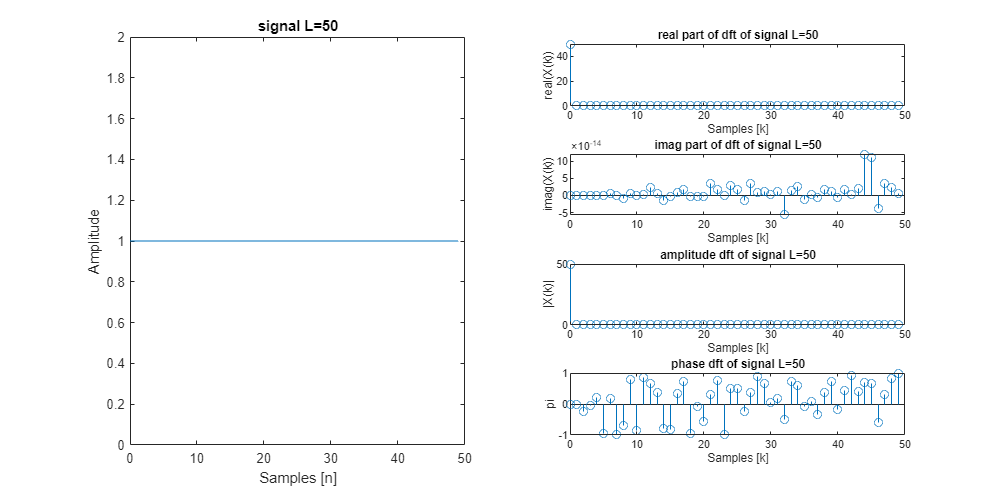

clc; clear; close all;
N = 50;
L = [1, 2, 5, 10, 25, 50];
for i = 1:length(L)
    sig = [ones(1, L(i)) zeros(1, N-L(i))];
    sig_dft = my_dft(sig);
    n = 0:N-1;
    
    fig = figure;
    fig.Position = [0, 0, 1000, 500];
    subplot(4, 2, [1,3,5,7])
    plot(n, sig)
    title(['signal L=', num2str(L(i))])
    ylabel('Amplitude')
    xlabel('Samples [n]')

    subplot(4,2,2)
    stem(n, real(sig_dft))
    title(['real part of dft of signal L=', num2str(L(i))])
    ylabel('real(X(k))')
    xlabel('Samples [k]')

    subplot(4,2,4)
    stem(n, imag(sig_dft))
    title(['imag part of dft of signal L=', num2str(L(i))])
    ylabel('imag(X(k))')
    xlabel('Samples [k]')

    subplot(4,2,6)
    stem(n, abs(sig_dft))
    title(['amplitude dft of signal L=', num2str(L(i))])
    ylabel('|X(k)|')
    xlabel('Samples [k]')

    subplot(4,2,8)
    stem(n, angle(sig_dft)/pi)
    title(['phase dft of signal L=', num2str(L(i))])
    ylabel('pi')
    xlabel('Samples [k]')
end

#### Obserwacje:

Prążki widma częstotliwościowego zerują się dla próbek występujących w odstępach N/L.

Część rzeczywista spektrum i spektum amplitudowe są symetryczne względem środka osi częstotliwości. Spektrum fazowe i część urojona spektrum są antysymetryczne względem środka osi częstotliwości.

Stosunek amplitud poszczególnych prążków w sygnale prostokątnym wynosi A/n gdzie A - amplituda sygnału prostokątnego, n - numer prążka

## **5. Splot liniowy i kołowy**

#### Obliczenia proszę wykonać zarówno analitycznie jak i za pomocą Matlaba. Proszę nie używać wbudowanej funkcji conv i dft.

a) Dla układu opisanego odpowiedzią impulsową ℎ(𝑛)=[1; 2; 3; 1] oblicz przy pomocy splotu liniowego sygnał wyjściowy 𝑦, gdy na wejście podany jest sygnał 𝑥(𝑛)=[1;1;0.5;−1;2;1;4]. Jaka jest długość sygnału na wyjściu układu?

b) Oblicz splot kołowy sygnałów ℎ(𝑛) i 𝑥(𝑛) dla minimalnej długości N=N1. Wyniki splotu liniowego i kołowego umieść na jednym wykresie. Ile pierwszych próbek obu splotów różni się między sobą? Oblicz różnicę między N pierwszymi próbkami splotu liniowego i kołowego, porównaj ją z wynikiem splotu liniowego. Co można zauważyć?

c) Oblicz splot liniowy sygnałów ℎ(𝑛) i 𝑥(𝑛) przy pomocy splotu kołowego. Jak dobrać długość N2 splotu kołowego, aby jego wynik był identyczny z wynikiem splotu liniowego?

d) Oblicz N punktowe widma DFT sygnałów ℎ(𝑛) i 𝑥(𝑛). Pomnóż odpowiadające sobie próbki obu widm 𝐻(𝑘).∗𝑋(𝑘). Poprzez N punktowe IDFT znajdź sygnał czasowy odpowiadający tak otrzymanemu widmu. Przyjmij N={N1, N2}. Porównaj z uprzednio otrzymanymi wynikami.

a) 

#### Opis problemu:

Podstawowym problemem jest obliczenie splotu liniowego dla układu opisanego odpowiedzią impulsową h[n] z sygnaęm wejściowym x[n]. 

#### Podstawy matematyczne:

Wzór na splot liniowy dla sygnałów dyskretnych:

                                                                                                                  

Z obliczeń wynika że splot y[n] dla sygnału wejściowego x[n] = [1, 1, 0.5, -1, 2, 1, 4] i odpowiedzi impulsowej h[n] = [1, 2, 3, 1] wynosi y[n] = [1, 3, 5.5, 4, 2.5, 2.5, 11, 13, 13, 4].

clc; clear; close all;
x = [1, 1, 0.5, -1, 2, 1, 4];
h = [1, 2, 3, 1];

y = lin_conv(x,h)

y =     1.0000    3.0000    5.5000    4.0000    2.5000    2.5000   11.0000   13.0000   13.0000    4.0000



y1 = conv(x,h)

y1 =     1.0000    3.0000    5.5000    4.0000    2.5000    2.5000   11.0000   13.0000   13.0000    4.0000


#### Obserwacje i wnioski:

Długość sygnału na wyjściu jest równa długości sygnałów x[n] i h[n] pomniejszona o n.

b)

#### Opis problemu:

Podstawowym problemem jest obliczenie splotu kołowego dla układu opisanego odpowiedzią impulsową h[n] z sygnałem wejściowym x[n]. 

#### Podstawy matematyczne:

Wzór na splot kołowy dla sygnałów dyskretnych:

                                                                             

Z obliczeń wynika że splot y[n] dla sygnału wejściowego x[n] = [1, 1, 0.5, -1, 2, 1, 4] i odpowiedzi impulsowej h[n] = [1, 2, 3, 1] wynosi y[n] = [13, 16, 9.5, 4, 2.5, 2.5, 11].

N = 7;
x = [1, 1, 0.5, -1, 2, 1, 4];
h = [1, 2, 3, 1];

y_lin = lin_conv(x,h)

y_lin =     1.0000    3.0000    5.5000    4.0000    2.5000    2.5000   11.0000   13.0000   13.0000    4.0000


y_circ = circ_conv(x,h)

y_circ =    14.0000   16.0000    9.5000    4.0000    2.5000    2.5000   11.0000


diff = y_circ - y_lin(1:N)

diff =     13    13     4     0     0     0     0


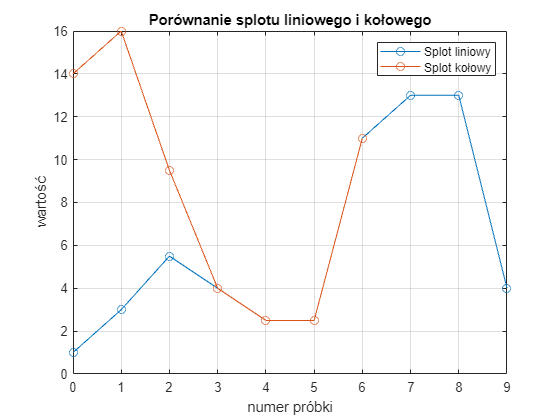

plot(0:length(y_lin)-1 , y_lin, '-o', 0:length(y_circ)-1, y_circ, '-o')
xlabel('numer próbki');
ylabel('wartość')
title('Porównanie splotu liniowego i kołowego')
legend('Splot liniowy', 'Splot kołowy')
box on
grid on

#### Obserwacje i wnioski:

Różnica pomiędzy splotami wynosi diff[n] = [13, 13, 4, 0, 0, 0, 0]. Wartości różnic między splotami są końcowymi elementami splotu liniowego. Z wykresu wynika, że trzy pierwsze próbki róznią się między splotami, a reszta jest taka sama.

c)

#### Opis problemu:

Aby obliczyć splot liniowy przy pomocy splotu kołowego wystarczy aby długości wektorów wejściowych x[n] oraz h[n] byłą równa długości splotu liniowego czyli długości x[n] oraz h[n] pomniejszona o jeden.

#### Podstawy matematyczne:

Wzór na splot kołowy dla sygnałów dyskretnych:

                                                                             

Z obliczeń wynika że splot y[n] dla sygnału wejściowego x[n] = [1, 1, 0.5, -1, 2, 1, 4] i odpowiedzi impulsowej h[n] = [1, 2, 3, 1] wynosi y[n] = [1, 3, 5.5, 4, 2.5, 2.5, 11, 13, 13, 4].


N = 10;
x = [1, 1, 0.5, -1, 2, 1, 4, 0, 0, 0];
h = [1, 2, 3, 1];

y_lin_by_circ = circ_conv(x,h)

y_lin_by_circ =     1.0000    3.0000    5.5000    4.0000    2.5000    2.5000   11.0000   13.0000   13.0000    4.0000


#### Obserwacje i wnioski:

Powyższy wynik jest równy wynikowi splotu liniowego.

d)

#### Opis problemu:

Aby wyznaczyć splot kołowy jako wynik IDFT musimy wykonać iloczyn widm DFT sygnałów wejściowych.

#### Podstawy matematyczne:

                                                                                                                       

Z obliczeń wynika, że  y[n] = [1, 3, 5.5, 4, 2.5, 2.5, 11, 13, 13, 4].

x = [1, 1, 0.5, -1, 2, 1, 4];
h = [1, 2, 3, 1];
X = [x, zeros(1, length(h)-1)];
H = [h, zeros(1, length(x)-1)];
X_dft = my_dft(X);
H_dft = my_dft(H);
Y_dft = H_dft.*X_dft;

y = idft(Y_dft)

y =    1.0000 - 0.0000i   3.0000 - 0.0000i   5.5000 - 0.0000i   4.0000 - 0.0000i   2.5000 - 0.0000i   2.5000 - 0.0000i  11.0000 + 0.0000i  13.0000 - 0.0000i  13.0000 + 0.0000i   4.0000 + 0.0000i


#### Obserwacje i wnioski:

Powyższy wynik jest równy wynikowi splotu liniowego.

a)

function Y = lin_conv(x,h)
    m = length(x);
    n = length(h);
    X = [x, zeros(1,n)];
    H = [h, zeros(1,m)];
    for i=1:n+m-1
        Y(i)=0;
        for j=1:m
            if(i-j+1>0)
                Y(i)=Y(i)+X(j)*H(i-j+1);
            else
            end
        end
    end
end

b, c)

function Y = circ_conv(x,h)
    l1 = length(x);
    l2 = length(h);
    N = max(l1, l2);
    X = [x, zeros(1, N-l1)];
    H = [h, zeros(1, N-l2)];
    Y = zeros(1, N);
    for n=1:N
        for m=1:N
        j=mod(n-m, N);
        j=j+1;
        Y(n)=Y(n)+X(m)*H(j);
        end
    end    
end

d)

function xn = idft(Xk)
    xn = zeros(size(Xk));
    for k=0 : (length(Xk)-1)
        xn(k+1) = 0;
        for n=0:(length(Xk)-1)
            xn(k+1) = xn(k+1) + Xk(n+1)*exp(1i*2*pi/length(Xk)*n*k)/length(Xk);
        end
    end
end

function Xk = my_dft(xn)
    Xk = zeros(size(xn));
    for i=0 : (length(xn)-1)
        Xk(i+1) = 0;
        for j=0 : (length(xn)-1)
            Xk(i+1) = Xk(i+1) + xn(j+1)*exp(-1i*2*pi/length(xn)*i*j);
        end    
    end
end

remove_errors

function output = remove_errors(input, treshold)
    re = (abs(real(input))>treshold) .* real(input);
    im = (abs(imag(input))>treshold) .* imag(input);
    output = re + 1i*im;
end